# Hypothesis Testing: Argus II retinal prosthesis 

Sam Coleman

### The Question 

We are primarily interested in understanding if the Argus II retinal prosthesis was effective in improving the subject's vision. The mean of the magnitude of difference between the target and the location of where the participant touched the screen. Each participant has the mean of 40 trials of the value for when the system is on and when the system is off. The data is continuous.

### Determine your null hypothesis, alternative hypothesis, alpha value

**Null Hypothesis (H0)**: Argus II has no effect on people's vision. If the null hypothesis were true, the system being on (Argus II on) and the system being off (Argus II off) would not impact the means for each subject.

**Alternative hypothesis**: Argus II had an effect on people's vision (the mean of the magnitude of difference between the target and where the participant touched the screen is different for system on and system off)

**Alpha value**: .05 

### Conduct your experiment and collect your data (Load Data).

data = readtable("argusData.csv") %import data

data = 29×3 table
    Participant    SystemOn    SystemOff
    ___________    ________    _________

       {'A'}         128          372   
       {'B'}         115          319   
       {'C'}         177          324   
       {'D'}         106          343   
       {'E'}         121          385   
       {'F'}         201          382   
       {'G'}         178          300   
       {'H'}         190          181   
       {'I'}         122          347   
       {'J'}         120          386   
       {'K'}         112          209   
       {'L'}         211           -1   
       {'M'}         103          404   
       {'N'}         102          536   
       {'O'}         199          327   
       {'P'}         237          312   


### Organize and clean the data

#### Understanding The Data

Participants are represented by Strings 'A' to 'AC'. There is a mean of 40 trials for both the system on and system off for each participant. 

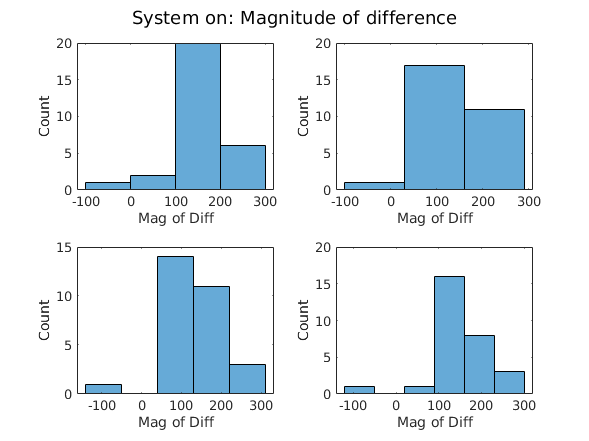

%Get an understanding of the distrubution: System On
figure();
sgtitle("System on: Magnitude of difference")
subplot(2,2,1)
histogram(data.SystemOn)
xlabel("Mag of Diff"); ylabel("Count");
subplot(2,2,2)
histogram(data.SystemOn, 3)
xlabel("Mag of Diff"); ylabel("Count");
subplot(2,2,3)
histogram(data.SystemOn, 5)
xlabel("Mag of Diff"); ylabel("Count");
subplot(2,2,4)
histogram(data.SystemOn, 6)
xlabel("Mag of Diff"); ylabel("Count");

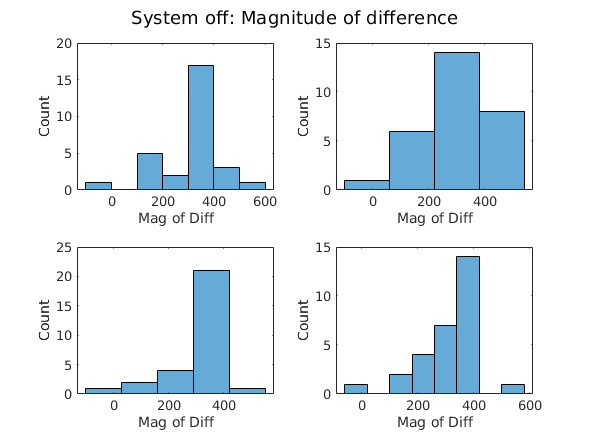

%Get an understanding of the distrubutionL System Off
figure();
sgtitle("System off: Magnitude of difference")
subplot(2,2,1)
histogram(data.SystemOff)
xlabel("Mag of Diff"); ylabel("Count");
subplot(2,2,2)
histogram(data.SystemOff,4)
xlabel("Mag of Diff"); ylabel("Count");
subplot(2,2,3)
histogram(data.SystemOff, 5)
xlabel("Mag of Diff"); ylabel("Count");
subplot(2,2,4)
histogram(data.SystemOff, 8)
xlabel("Mag of Diff"); ylabel("Count");

Looking at the histograms, we see there are negative values. This is not expected as the values are "the mean of the magnitude of difference." Below, I am looking closer into the negative values (based on the data I would expect everything to be >=0 but that is not the case). These values are not expected so they will be considered outliers, and not used in the testing.

#### Investiage Outliers

%see (the number of and values of) negative data in both SystemOn and
%SystemOff
sum(data.SystemOn < 0) %1 negative SystemOn Val

ans = 1

data.SystemOn(data.SystemOn < 0) %val is -99

ans = -99


sum(data.SystemOff < 0) %1 negative SystemOff Val

ans = 1

data.SystemOff(data.SystemOff < 0) %val is -1

ans = -1

%look at the summary of the data
summary(data)

Variables:

    Participant: 29×1 cell array of character vectors

    SystemOn: 29×1 double

        Values:

            Min         -99   
            Median      128   
            Max         268   

    SystemOff: 29×1 double

        Values:

            Min          -1   
            Median      340   
            Max         536   



### Determine what types of tests/measurements are appropriate to answer your question.

We have a set of data for each participant with using the Argus II and a set of data without using the Argus II. Therefore, I will use a **paired sample T test. **

Assumptions of a paired sample T test:

- The dependent variable must be continuous (interval/ratio). 

- The observations are independent of one another.

- The dependent variable should be approximately normally distributed.

- The dependent variable should not contain any outliers.

Since the paired sample T test assumes no outliers, I am going to remove the negative values from SystemOn and SystemOff (not use them when I do the paired sample t test or calculate any other values). Again, this is because we are measuring the magnitude of the difference between the target (white square stimulus) and the location that the subject touched the screen, so negative values are outliers (since negative is not a magnitude). 

Test for normal distribution using lillietest:

[h_off, p_off] = lillietest(data.SystemOff(data.SystemOff >= 0))

h_off = 1

p_off = 0.0356

[h_on, p_on] = lillietest(data.SystemOn(data.SystemOn >= 0))

h_on = 1

p_on = 0.0196

Based on the results from the lilietest (and from visually looking at the histograms), we can see that the data is not normally distrubuted. However, we will still proceed with the paired sample T test.

### Calculate appropriate measurements / tests

To reiterate our null hypothesis: H0 is that the Argus II has no effect on people's accuracy while performing this task (which would suggest it has no impact on people's vision). 

%Perform the paired sample T Test (ignoring the negative values)

%create variables to store only positive data
sys_on_pos = data.SystemOn(data.SystemOn >= 0);
sys_off_pos = data.SystemOff(data.SystemOff >= 0);

%run paired t test
alpha = .05;
[H, P, CI, STATS] = ttest(sys_on_pos, sys_off_pos, "Alpha", alpha)

H = 1

P = 2.7040e-09

CI =  -211.3375
 -130.5196


STATS = struct with fields:
    tstat: -8.6792
       df: 27
       sd: 104.2113


#### Understanding the Output of Paired T Test

H = 1 means we *reject the null hypothesis* with our alpha value (currently .05). P is the p-value (the probability of getting our test statistic) or data more extreme given that our null hypothesis is true. As our p-value shows, the data is very unlikely if the null hypothesis is true, so we reject the null hypothesis. 

CI is the confidence interval, which in this case is a 95% confidence interval (1 - alpha). In this case, there is a 95% probability that any given confidence interval from a random sample will contain the true population mean.

The STATS gives some other information. As shown, the t-value is -8.6792.  A t-value of 0 indicates that the sample results exactly equal the null hypothesis. As the effect size (difference between the sample estimate and null hypothesis) increases, the absolute value of the t-value increases. This t-value, once again, tells us we should reject the null hypothesis. We have 27 degrees of freedom, which is the total number of observations minus one (so 28 - 1 = 27). The sample standard deviation is 104.2113.

#### Effect Size

We will use the Cohen's d measure of effect size:

cohensd = (mean(sys_on_pos) - mean(sys_off_pos))/std(sys_on_pos, sys_off_pos)

cohensd = -3.2499

This effect size is very large. Note how .8 is often considered a "large" effect size, and our effect size is 3.2499. This value is the number of standard deviations away the mean is from the mean expected for our null hypothesis. In this case, the effect size represents the difference in accuracy recording between using the Argus II (system on) and not using the Argus II (system off), measured in standard deviations. 

### Graph to illustrate findings.

To give a better sense of the findings, below is a histogram with both SystemOn and SystemOff overlayed on eachother. Once again, the negative outliers are not included. I used the automatic number of bins MATLAB calculates for this histogram. 

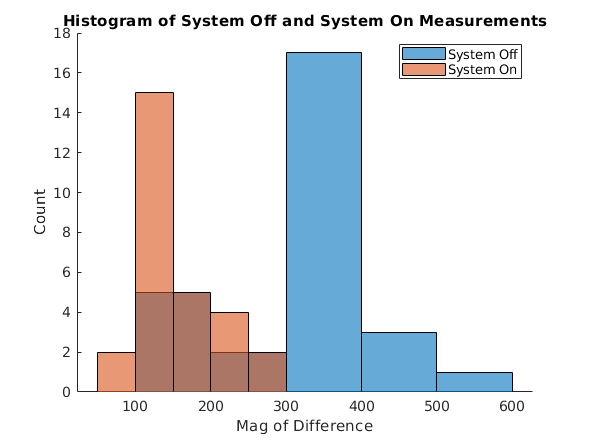

figure();
hold on;
histogram(sys_off_pos)
histogram(sys_on_pos)
title("Histogram of System Off and System On Measurements")
xlabel("Mag of Difference")
ylabel("Count")
legend("System Off", "System On")
hold off;

This histogram illustrates the differences in results between using the Argus II system and not using it. It also illustrates the large effect size, as the two samples don't overlap a lot. 

### Summary of Findings

In this study, we compared the impact of using the Argus II Retinal Prosthesis on particpant's accuracy in determining the center of a white square stimulus. The less the magnitude of difference between the centre of the stimulus and the participant's location touched, the more accurate they were. These samples were averaged over 40 trials and recorded for SystemOn and SystemOff for each participant.  With an alpha value of .05, t(27) = -8.6792 and a p-value of 2.7040e-9. Thus, the null hypothesis is rejected. We also calcualted a Cohen's d easure of effect size of -3.25, indicating a large overall effect size.